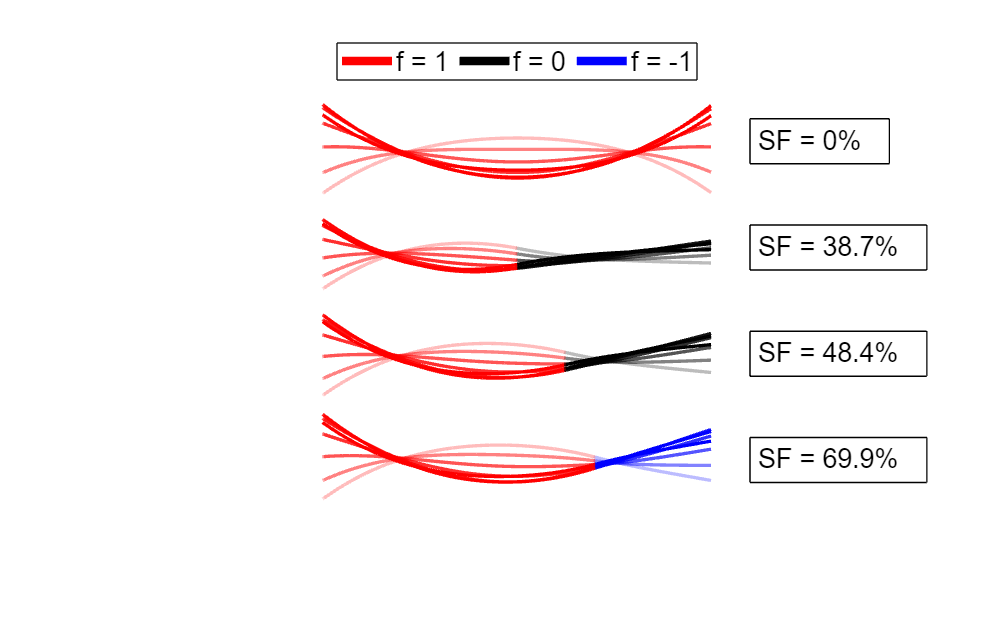

N = 1000;
eta = exp(-pi*1i/8);

old_xi_values = (2*(1:N) - 1)./(2*N);
xi_values = (2*(1:N) - 1)./(2*N);
Sp = 4.7;

        G = zeros(N, N);
        G_prime = zeros(N, N);
        G_prime_prime = zeros(N, N);
        
        for b = 1:N
            xi = xi_values(b);
            x_minus = xi_values(1:b);
            x_plus = xi_values(b:N);
        
            M = [1 1 1 1 0 0 0 0; 1 1i -1 -1i 0 0 0 0; 0 0 0 0 exp(Sp*eta) exp(Sp*eta*1i) exp(-Sp*eta) exp(-Sp*eta*1i); 0 0 0 0 exp(Sp*eta) 1i*exp(Sp*eta*1i) -exp(-Sp*eta) -1i*exp(-Sp*eta*1i); -exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi)];
            coeff = linsolve(M, [0; 0; 0; 0; 0; 0; 0; 1/((Sp^3)*(eta^3))]);

            G((1:b),b) = (coeff(1)*exp(Sp*eta*x_minus) + coeff(2)*exp(Sp*eta*x_minus*1i) + coeff(3)*exp(-Sp*eta*x_minus) + coeff(4)*exp(-Sp*eta*x_minus*1i));
        
            G((b:N),b) = (coeff(5)*exp(Sp*eta*x_plus) + coeff(6)*exp(Sp*eta*x_plus*1i) + coeff(7)*exp(-Sp*eta*x_plus) + coeff(8)*exp(-Sp*eta*x_plus*1i));

        
            G_prime((1:b),b) = Sp*eta*(coeff(1)*exp(Sp*eta*x_minus) + 1i*coeff(2)*exp(Sp*eta*x_minus*1i) - coeff(3)*exp(-Sp*eta*x_minus) - 1i*coeff(4)*exp(-Sp*eta*x_minus*1i));
        
            G_prime((b:N),b) = Sp*eta*(coeff(5)*exp(Sp*eta*x_plus) + 1i*coeff(6)*exp(Sp*eta*x_plus*1i) - coeff(7)*exp(-Sp*eta*x_plus) - 1i*coeff(8)*exp(-Sp*eta*x_plus*1i));
        
            G_prime_prime((1:b),b) = ((Sp*eta)^2)*(coeff(1)*exp(Sp*eta*x_minus) - coeff(2)*exp(Sp*eta*x_minus*1i) + coeff(3)*exp(-Sp*eta*x_minus) - coeff(4)*exp(-Sp*eta*x_minus*1i));
        
            G_prime_prime((b:N),b) = ((Sp*eta)^2)*(coeff(5)*exp(Sp*eta*x_plus) - coeff(6)*exp(Sp*eta*x_plus*1i) + coeff(7)*exp(-Sp*eta*x_plus) - coeff(8)*exp(-Sp*eta*x_plus*1i));


        end
        G_s = -0.5*(imag(G_prime) + imag(G_prime.'));
        
        G_swim = G_s;
        
        [A, B] = eig(G_swim);

        lambda = B(N, N)/N;

        g_plus = A(:, end)*sqrt(N);
        g_minus = A(:, end-1)*sqrt(N);

g_s = (g_plus + flip(g_plus));
g_a = (g_plus - flip(g_plus));

g_s_int = zeros(N, 1);
g_a_int = zeros(N, 1);

g_s_int(1) = g_s(1)/N;
g_a_int(1) = g_a(1)/N;

for n = 2:N
    g_s_int(n) = g_s_int(n-1) + g_s(n)/N;
    g_a_int(n) = g_a_int(n-1) + g_a(n)/N;
end


temp = interpn(g_s);
g_s = temp(2:2:(end-1)).';
g_s = [g_s; 0];
temp = interpn(g_a);
g_a = temp(2:2:(end-1)).';
g_a = [g_a; 0];
temp = interpn(xi_values);
xi_values = temp(2:2:(end-1)).';
xi_values = [xi_values; 1];

xi_1_star_index = 625;
xi_1_star = xi_values(xi_1_star_index);

reverse_g_s_int = g_s_int(end) - g_s_int;
reverse_g_a_int = g_a_int(end) - g_a_int;

xi_2_star_index = 701;
xi_2_star = xi_values(xi_2_star_index);

plot(-1, -1, 'r', 'LineWidth', 5)
hold on
plot(-1, -1, 'k', 'LineWidth', 5)
plot(-1, -1, 'b', 'LineWidth', 5)
legend('f = 1  ', 'f = 0  ', 'f = -1  ', 'AutoUpdate', 'off', 'Location', 'northoutside', 'Fontsize', 16, 'NumColumns', 3)

speeds = zeros(1, 4);
speeds(2) = g_s_int(N/2)*g_a_int(N/2);
speeds(3) = g_s_int(xi_1_star_index)*g_a_int(xi_1_star_index);
speeds(4) = (g_s_int(xi_2_star_index) - reverse_g_s_int(xi_2_star_index))*(g_a_int(xi_2_star_index) - reverse_g_a_int(xi_2_star_index));

f1 = ones(1, N);
f2 = [ones(1, N/2), zeros(1, N/2)];
f3 = [ones(1, xi_1_star_index), zeros(1, N - xi_1_star_index)];
f4 = [ones(1, xi_2_star_index), zeros(1, N - xi_2_star_index)];

G_int1 = G*f1.'/N;
G_int2 = G*f2.'/N;
G_int3 = G*f3.'/N;
G_int4 = G*f4.'/N;

G_prime_prime_int1 = G_prime_prime*f1.'/N;
G_prime_prime_int2 = G_prime_prime*f2.'/N;
G_prime_prime_int3 = G_prime_prime*f3.'/N;
G_prime_prime_int4 = G_prime_prime*f4.'/N;

time_steps = linspace(0, pi, 7);

% plot([0, 1], [4, 4], 'r', 'LineWidth', 5)
% hold on
% plot([0.5, 1], [3, 3], 'k', 'LineWidth', 5)
% plot([xi_2_star, 1], [1, 1], 'b', 'LineWidth', 5)
hold on

% plot([0, 0.5], [3, 3], 'r', 'LineWidth', 5)
% plot([0, xi_1_star], [2, 2], 'r', 'LineWidth', 5)
% plot([xi_1_star, 1], [2, 2], 'k', 'LineWidth', 5)
% plot([0, xi_2_star], [1, 1], 'r', 'LineWidth', 5)
xlim([-0.5, 1.5])
ylim([0, 9])

annotation('textbox', [0.75, 0.51, 0.3, 0.3], 'String', "SF = " + num2str(100*speeds(1), 3) + "%", 'FitBoxToText', 'on', 'FontSize', 16)
annotation('textbox', [0.75, 0.34, 0.3, 0.3], 'String', "SF = " + num2str(100*speeds(2), 3) + "%", 'FitBoxToText', 'on', 'FontSize', 16)
annotation('textbox', [0.75, 0.17, 0.3, 0.3], 'String', "SF = " + num2str(100*speeds(3), 3) + "%", 'FitBoxToText', 'on', 'FontSize', 16)
annotation('textbox', [0.75, 0, 0.3, 0.3], 'String', "SF = " + num2str(100*speeds(4), 3) + "%", 'FitBoxToText', 'on', 'FontSize', 16)
axis off

for time_counter = 1:length(time_steps)
    temp1 = real((G_prime_prime_int1)*exp(1i*time_steps(time_counter)))*16;
    temp2 = real((G_prime_prime_int2)*exp(1i*time_steps(time_counter)))*16;
    temp3 = real((G_prime_prime_int3)*exp(1i*time_steps(time_counter)))*16;
    temp4 = real((G_prime_prime_int4)*exp(1i*time_steps(time_counter)))*16;

    patch([old_xi_values, flip(old_xi_values)], 8 + [temp1; flip(temp1)], 'r', 'EdgeColor', 'r', 'LineWidth', 2, 'EdgeAlpha', 1 - (time_counter-1)/length(time_steps))
    patch([old_xi_values(((N/2)):N), flip(old_xi_values(((N/2)):N))], 6 + [temp2(((N/2)):N); flip(temp2(((N/2)):N))], 'k', 'EdgeColor', 'k', 'LineWidth', 2, 'EdgeAlpha', 1 - (time_counter-1)/length(time_steps))
    patch([old_xi_values((xi_2_star_index):N), flip(old_xi_values((xi_2_star_index):N))], 2 + [temp4(xi_2_star_index:N); flip(temp4(xi_2_star_index:N))], 'b', 'EdgeColor', 'b', 'LineWidth', 2, 'EdgeAlpha', 1 - (time_counter-1)/length(time_steps))
    
    
    patch([old_xi_values(1:(N/2)), flip(old_xi_values(1:(N/2)))], 6 + [temp2(1:(N/2)); flip(temp2(1:(N/2)))], 'r', 'EdgeColor', 'r', 'LineWidth', 2, 'EdgeAlpha', 1 - (time_counter-1)/length(time_steps))

    
    patch([old_xi_values(1:(xi_1_star_index)), flip(old_xi_values(1:(xi_1_star_index)))], 4 + [temp3(1:(xi_1_star_index)); flip(temp3(1:(xi_1_star_index)))], 'r', 'EdgeColor', 'r', 'LineWidth', 2, 'EdgeAlpha', 1 - (time_counter-1)/length(time_steps))
    patch([old_xi_values((xi_1_star_index):N), flip(old_xi_values((xi_1_star_index):N))], 4 + [temp3(xi_1_star_index:N); flip(temp3(xi_1_star_index:N))], 'k', 'EdgeColor', 'k', 'LineWidth', 2, 'EdgeAlpha', 1 - (time_counter-1)/length(time_steps))

    
    patch([old_xi_values(1:(xi_2_star_index)), flip(old_xi_values(1:(xi_2_star_index)))], 2 + [temp4(1:(xi_2_star_index)); flip(temp4(1:(xi_2_star_index)))], 'r', 'EdgeColor', 'r', 'LineWidth', 2, 'EdgeAlpha', 1 - (time_counter-1)/length(time_steps))
    

end

x0=10;
y0=10;
width=800;
height=500;

set(gcf,'position',[x0,y0,width,height])